EV_data = import_EV_data(9, 30, 1);
hdf5FilePath= "here.hd";


% Get unique cycles
cycles = unique(EV_data.Cycle);

% Loop through each unique cycle
for i = 1:length(cycles)
    cycleNumber = cycles(i);
    
    % Filter data for the current cycle
    cycleData = EV_data(EV_data.Cycle == cycleNumber, :);
    
    % Convert table to a structure for HDF5 storage
    cycleStruct = table2struct(cycleData, 'ToScalar', true);
    
    % Create a group name for the current cycle
    groupName = sprintf('/Cycle%d', cycleNumber);
    
    % Save each field of the structure as a dataset within the group
    fieldNames = fieldnames(cycleStruct);
    for j = 1:numel(fieldNames)
        datasetName = sprintf('%s/%s', groupName, fieldNames{j});
        h5create(hdf5FilePath, datasetName, size(cycleStruct.(fieldNames{j})));
        h5write(hdf5FilePath, datasetName, cycleStruct.(fieldNames{j}));
    end
end

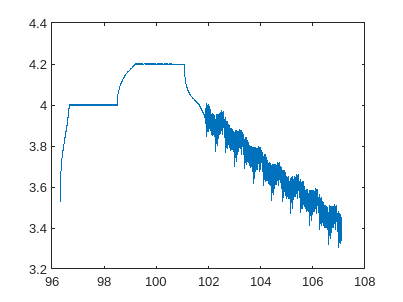


current_cycle = EV_data(EV_data.Cycle == 10, :);
plot(current_cycle.t, current_cycle.V)


% Specify the cycle number you want to read
cycleNumber = 10;

% Generate the group name for the specified cycle
groupName = sprintf('/Cycle%d', cycleNumber);

% Determine the datasets within this group (optional, if you know the dataset names you can skip this step)
info = h5info(hdf5FilePath, groupName);
datasetNames = {info.Datasets.Name};

% Initialize a structure to hold the data from this cycle
cycleData = struct();

% Read each dataset within the cycle group
for i = 1:length(datasetNames)
    datasetName = sprintf('%s/%s', groupName, datasetNames{i});
    cycleData.(datasetNames{i}) = h5read(hdf5FilePath, datasetName);
end

% Now, cycleData contains all the datasets for cycle 10
plot(cycleData.t, cycleData.V)